# Lab Assignment 1: Solving Systems of Linear Equations Describing Electrical Circuits

**Your full name:** Xu Ji

**Your utorID:** 1008784406

## A more complex circuit

Consider the following circuit with a variable resistor $R_L$:

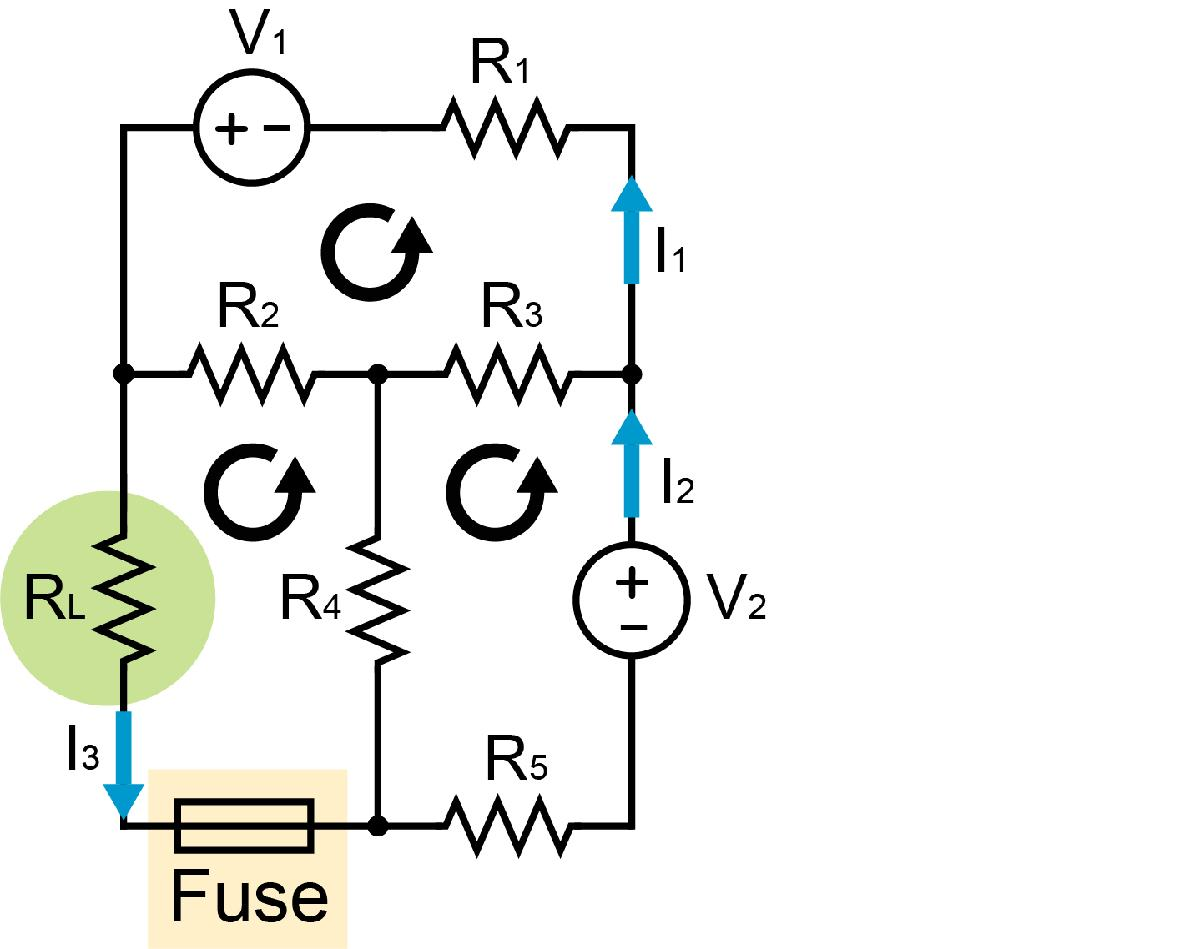

We can construct a system of equations to describe this circuit using a combination of KVL and KCL:

*        top loop: *$V_1 -R_2 \left(I_1 -I_3 \right)+R_{3\;} \left(I_2 -I_1 \right)-R_1 I_1 =0$

*        left loop:* ${-R}_L I_{3\;} -R_4 \left(I_3 -I_{2\;} \right)+R_{2\;} \left(I_{1\;} -I_3 \right)=0$

*        outmost loop: *$V_1 -R_L I_3 -R_5 I_{2\;} +V_2 -R_1 I_1 =0$ 

## Problem 1: Finding the minimum resistance to keep the fuse intact

The fixed circuit parameters are defined here for you.

    Resistors: 

R1 = 8; R2 = 4; R3 = 4; R4 = 6; R5 = 1;  % Units: Ohms

    Voltage sources: 

V1 = 120; V2 = 120; % Units: Volts

**What must the variable resistor (**$R_L$**) be set to in order to prevent a 5 Amp fuse from melting?**

- Tell MATLAB to display the value for $R_L$ to 1 decimal place using fprintf and matrix indexing.  

- eg. you should be getting this value directly from a variable in memory

Hint: Include the unknown resistance as a variable in your system of equations.

            eg.  $x=\left\lbrack \begin{array}{c}
I_1 \\
I_2 \\
R_L 
\end{array}\right\rbrack$

I3 = 5; % unit: ampre
A = [-R1 - R2 - R3, R3, 0; R2, R4, -I3; -R1, -R5, -I3];
b = [-V1 - R2 * I3; R4 * I3 + R2 * I3; -V1 - V2]; % constructs an augmented matrix for the loop
x = linsolve(A, b); % solves the augmented matrix into RREF form
final_answer = x(3);   % stores the required element
fprintf('The minimum R_L to prevent melting the fuse is %.1f Ohms', final_answer)

The minimum R_L to prevent melting the fuse is 22.9 Ohms

## Problem 2: Using a for loop to approximate the answer

In many real life scenarios, an numerical estimate is often adequate for most engineering applications, especially because it may not be feasible to compute an exact solution.

**Use a for-loop to solve this circuit for varying values of **$R_L$** to find the resitance in **$R_L$** that will lead to excessive current through the fuse.**

- Test values of $R_L$ between 0 and 50 Ohms, in steps of 0.5 Ohms

- Save the resultant current that would be going through the fuse

- Print the value of $R_L$ that will cause the 5 Amp fuse to melt

Hints:

- In this part, we need to reconstruct our system of equations. 

- Now, our unknowns will be $I_1 ,I_{2\;}$, and $I_3$. We compute the value of $I_3$ given a some value for $R_L$.

RList = []; % saves all the tested resistence (RL)
IList = []; % saves all the respective current through fuse (I3)
LastR = 0; % sets initial value for RL, unit: Ohm
fuse_intact = false; % flag used to indicate if the fuse is melted
for RL = 0 : 0.5 : 50 % for loop with base 0, step 0.5, ends at RL = 50
    A = [-R2 - R3 - R1, R3, R2; R2, R4, -RL - R4 - R2; -R1, -R5, -RL];
    b = [-V1; 0; -V1 - V2]; % implements an augmented matrix for the loop
    x = linsolve(A, b); % solves the augmented matrix into RREF form
    I3 = x(3); % slices the vertor to get I3
    RList(end + 1) = RL; % appends the tested resistence to list
    IList(end + 1) = I3; % appends the respective current to list
    if fuse_intact == false && I3 <= 5 % only enters the branch when the first RL value does not melt the fuse
        Rout = LastR; % stores the output value for future
        fuse_intact = true; % toggles flag
    end
    LastR = RL; % updates the LastR value
end
fprintf('The maximum resistence that leads to the melting of the fuse is %.1f Ohms', Rout) % outputs the stored value where fuse is melted

The maximum resistence that leads to the melting of the fuse is 22.5 Ohms

**Generate a scatter plot of your simulation:**

- Show the variable resistance on the x-axis and the resultant current through the fuse on the y-axis

- Include a horizontal line indicating the maximum current of the fuse

- Remember to label your plot axes and add a plot title

Hint: The following commands may be useful.

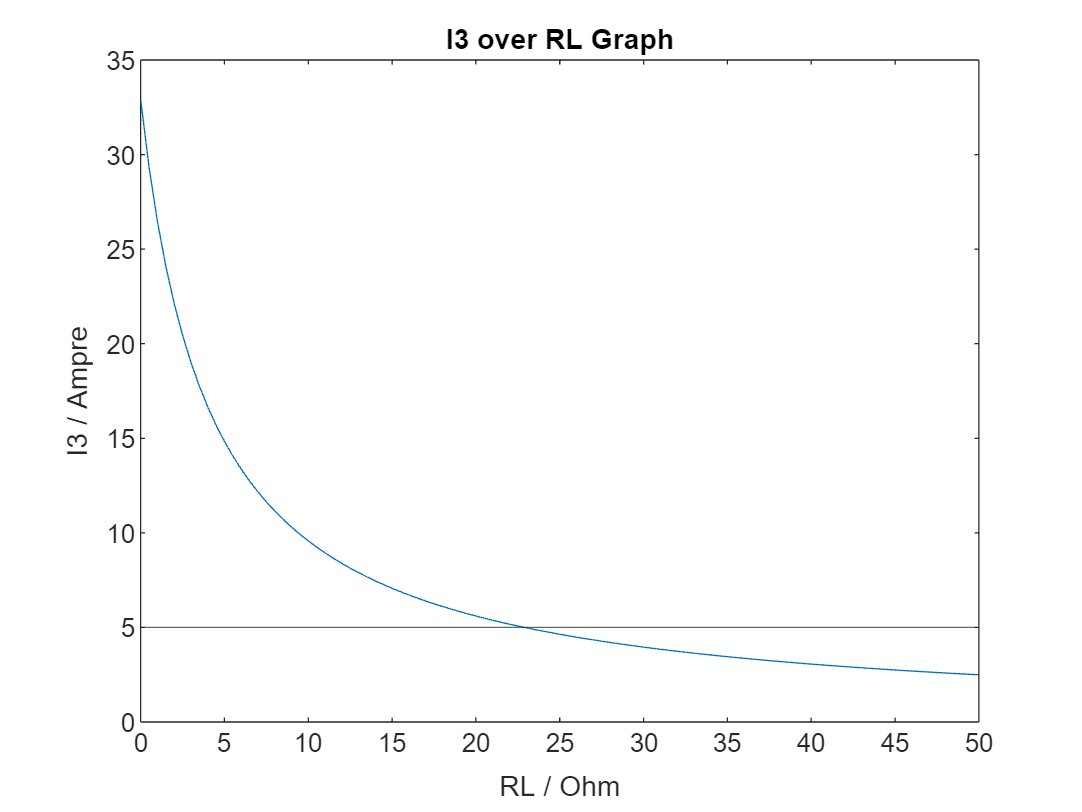

plot(RList, IList) % plots the graph with elements in RList as independent variable, elements in IList as dependent variable
yline(5) % indicates the maximum current in the fuse
title('I3 over RL Graph') % lables the title of the graph
xlabel('RL / Ohm'), ylabel('I3 / Ampre') % lables the y, x axises

## Problem 3: Simulating the current through $I_2$ as the fuse melts

When a fuse melts, it completely interrupts the flow of current through the circuit at that point.

Imagine an experimenter set-up this circuit in the lab, with the variable resistor ($R_L$) initially set to 50 Ohms, and a fuse that will melt above 5 Amps. The experimenter gradually reduce the resistance in the resistor until it reaches 0 Ohms. **Plot the current **$I_2$** against the resistance in **$R_L$ **as the resistor is adjusted from 50 Ohms down to 0 Ohms.**

Hints: 

- Start by copying the for-loop you wrote for Problem 2B above.

- You may need to solve the circuit twice in the for-loop: once to determine if the fuse will melt, and once again to solve the circuit accounting for if the fuse is melted.

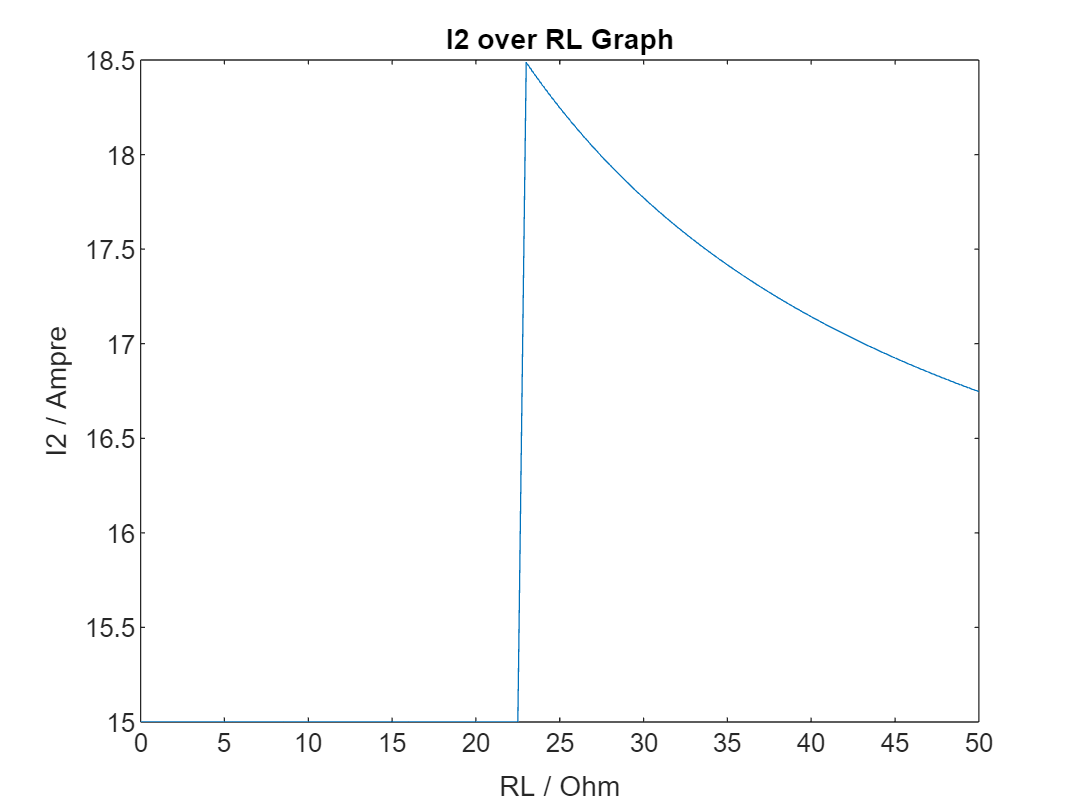

RList = []; % saves all the tested resistence (RL)
IList = []; % saves all the respective current through fuse (I3)
fuse_intact = true; % flag used to indicate if the fuse is melted
for RL = 50 : -0.5 : 0 % for loop with base 50, step -0.5, ends at RL = 0
    A = [-R2 - R3 - R1, R3, R2; R2, R4, -RL - R4 - R2; -R1, -R5, -RL];
    b = [-V1; 0; -V1 - V2]; % implements an augmented matrix for the loop when the fuse is intact
    x = linsolve(A, b); % solves the augmented matrix into RREF form
    I3 = x(3); % slices the vertor to get I3
    I2 = x(2); % assume fuse is intact, slices the vertor to get I3
    if fuse_intact == true % if the fuse is not melted yet
        if I3 <= 5 % if current will not melt the fuse 
            RList(end + 1) = RL; % appends the tested resistence to list
            IList(end + 1) = I2; % appends the respective current to list
        else % when the fuse is melted for the first time
            fuse_intact = false; % toggles flag
            C = [-R2 - R3 - R1, R3; R3, -R3 - R4 - R5];
            d = [-V1; -V2]; % implements an augmented matrix for the loop when the fuse is melted
            y = linsolve(C, d); % solves the augmented matrix into RREF form
            I2 = y(2); % slices the vertor to get I2
            RList(end + 1) = RL; % appends the tested resistence to list
            IList(end + 1) = I2; % appends the respective current to list
        end
    else % when the fuse is already melted
        C = [-R2 - R3 - R1, R3; R3, -R3 - R4 - R5];
        d = [-V1; -V2]; % implements an augmented matrix for the loop when the fuse is melted
        y = linsolve(C, d); % solves the augmented matrix into RREF form
        I2 = y(2); % slices the vertor to get I2
        RList(end + 1) = RL; % appends the tested resistence to list
        IList(end + 1) = I2; % appends the respective current to list
    end
end
plot(RList, IList) % plots the graph with elements in RList as independent variable, elements in IList as dependent variable
title('I2 over RL Graph') % lables the title of the graph
xlabel('RL / Ohm'), ylabel('I2 / Ampre') % lables the y, x axises